# **fourth Optimal Control Project**

# **Designing a Discrete Infinite-Time Tracking LQT Using Deviation Variables for a Linear Quadcopter System.**

## Ali Eidizadeh                            ali80ei@gmail.com

## Amirhadi Keyvan     amirhadikeyvan@gmail.com

## Parameters

clear all
close all
clc

g = 9.8;
m = 0.65;
Ix = 7.5e-3;
Iy = 7.5e-3;
Iz = 1.3e-2;

## Continuous-time linearized system


A = [0 1 0 0 0 0 0 0 0 0 0 0;
     0 0 0 0 0 0 0 0 g 0 0 0;
     0 0 0 1 0 0 0 0 0 0 0 0;
     0 0 0 0 0 0 g 0 0 0 0 0;
     0 0 0 0 0 1 0 0 0 0 0 0;
     0 0 0 0 0 0 0 0 0 0 0 0;
     0 0 0 0 0 0 0 1 0 0 0 0;
     0 0 0 0 0 0 0 0 0 0 0 0;
     0 0 0 0 0 0 0 0 0 1 0 0;
     0 0 0 0 0 0 0 0 0 0 0 0;
     0 0 0 0 0 0 0 0 0 0 0 1;
     0 0 0 0 0 0 0 0 0 0 0 0];

B = [0 0 0 0;
     0 0 0 0;
     0 0 0 0;
     0 0 0 0;
     0 0 0 0;
     1/m 0 0 0;
     0 0 0 0;
     0 1/Ix 0 0;
     0 0 0 0;
     0 0 1/Iy 0;
     0 0 0 0;
     0 0 0 1/Iz];
C = [1 0 0 0 0 0 0 0 0 0 0 0;
     0 0 1 0 0 0 0 0 0 0 0 0;
     0 0 0 0 1 0 0 0 0 0 0 0;
     0 0 0 0 0 0 1 0 0 0 0 0;
     0 0 0 0 0 0 0 0 1 0 0 0;
     0 0 0 0 0 0 0 0 0 0 1 0];
D = zeros(size(C,1),size(B,2));

## Discretization

Ts = 0.001; 
sys_c = ss(A,B,C,D);
sys_d = c2d(sys_c, Ts);
Ad = sys_d.A;
Bd = sys_d.B;

## LQR design

Q = diag([20 1 20 1 20 1 1 1 1 1 1 1]);
R = 0.01 * eye(4);                         

[Kd,~,~] = dlqr(Ad, Bd, Q, R);

## Simulation setup

T_end = 50;
N = round(T_end / Ts);
x = zeros(12, N);          
u = zeros(4, N);           
r = zeros(12, N);          
t = (0:N-1)*Ts;

xod = 0.5 * cos(t/2);
yod = 0.5 * sin(t/2);
zod = -1 - t/10;

r(1,:) = xod;
r(3,:) = yod;
r(5,:) = zod;

r_dot = diff(r,1,2) / Ts;
r_dot(:,end+1) = r_dot(:,end);

Bpinv = pinv(Bd);

## Simulation loop

for k = 1:N-1
    u(:,k) = -Kd*(x(:,k) - r(:,k)) + Bpinv * (r_dot(:,k) - Ad*r(:,k));
    x(:,k+1) = Ad*x(:,k) + Bd*u(:,k);
end

## Figure 1: Positions x, y, z (with references)

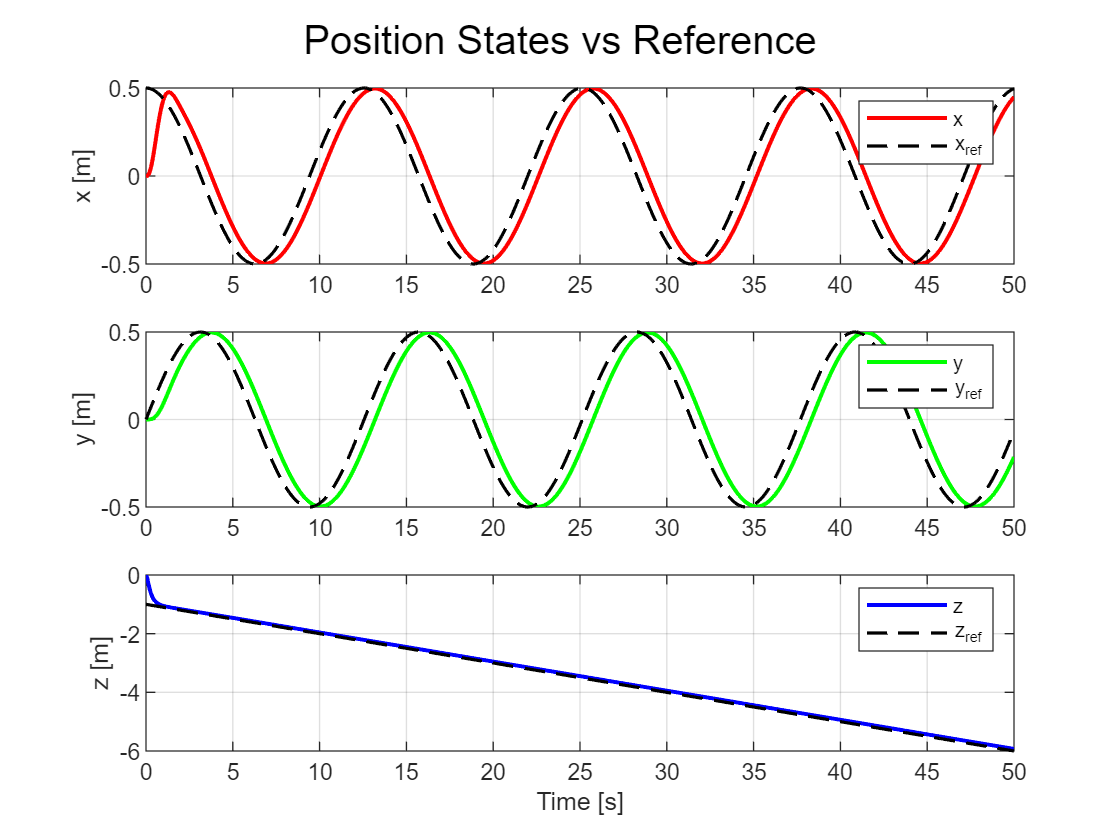

x=x';

figure;
subplot(3,1,1);
plot(t, x(:,1), 'r', 'LineWidth', 1.5); hold on;
plot(t, xod, 'k--', 'LineWidth', 1.2);
ylabel('x [m]'); legend('x', 'x_{ref}'); grid on;

subplot(3,1,2);
plot(t, x(:,3), 'g', 'LineWidth', 1.5); hold on;
plot(t, yod, 'k--', 'LineWidth', 1.2);
ylabel('y [m]'); legend('y', 'y_{ref}'); grid on;

subplot(3,1,3);
plot(t, x(:,5), 'b', 'LineWidth', 1.5); hold on;
plot(t, zod, 'k--', 'LineWidth', 1.2);
xlabel('Time [s]'); ylabel('z [m]'); legend('z', 'z_{ref}');
grid on;
sgtitle('Position States vs Reference');

## Figure 2: Velocities x' y' z'

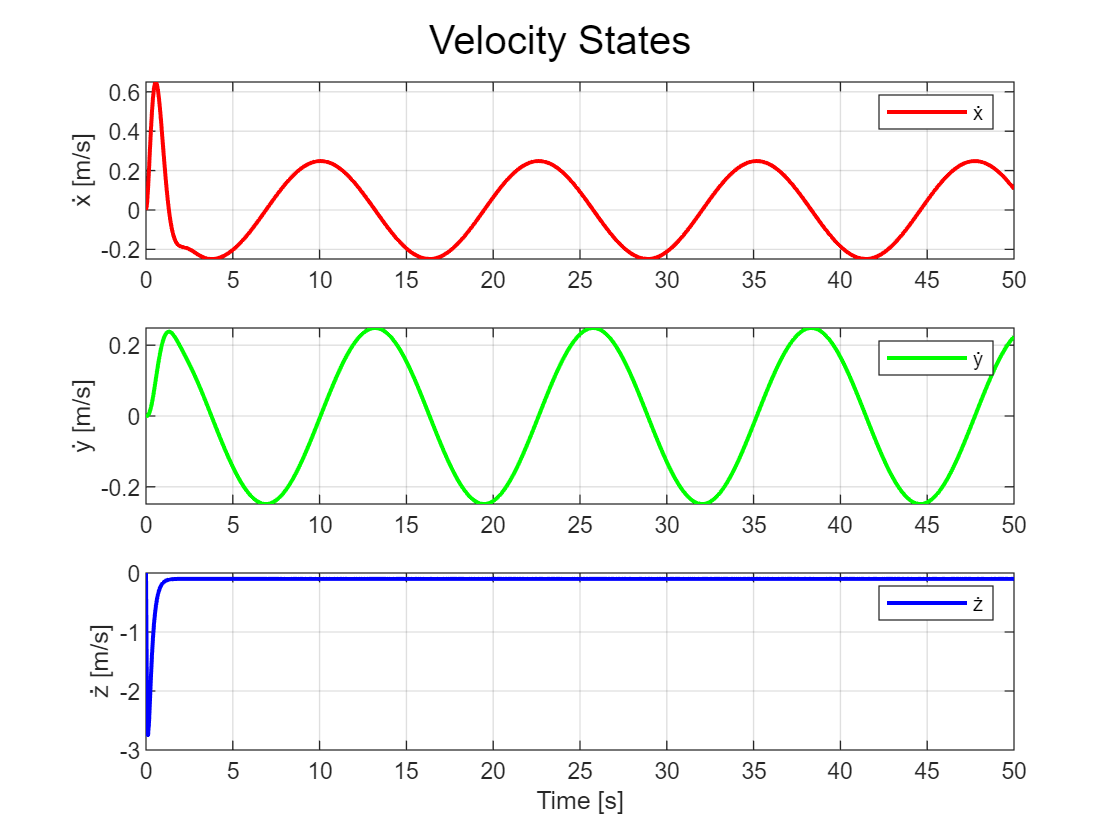

figure;
subplot(3,1,1);
plot(t, x(:,2), 'r', 'LineWidth', 1.5);
ylabel('ẋ [m/s]'); legend('ẋ'); grid on;

subplot(3,1,2);
plot(t, x(:,4), 'g', 'LineWidth', 1.5);
ylabel('ẏ [m/s]'); legend('ẏ'); grid on;

subplot(3,1,3);
plot(t, x(:,6), 'b', 'LineWidth', 1.5);
xlabel('Time [s]'); ylabel('ż [m/s]'); legend('ż'); grid on;
sgtitle('Velocity States');

## Figure 3: Euler Angles φ, θ, ψ

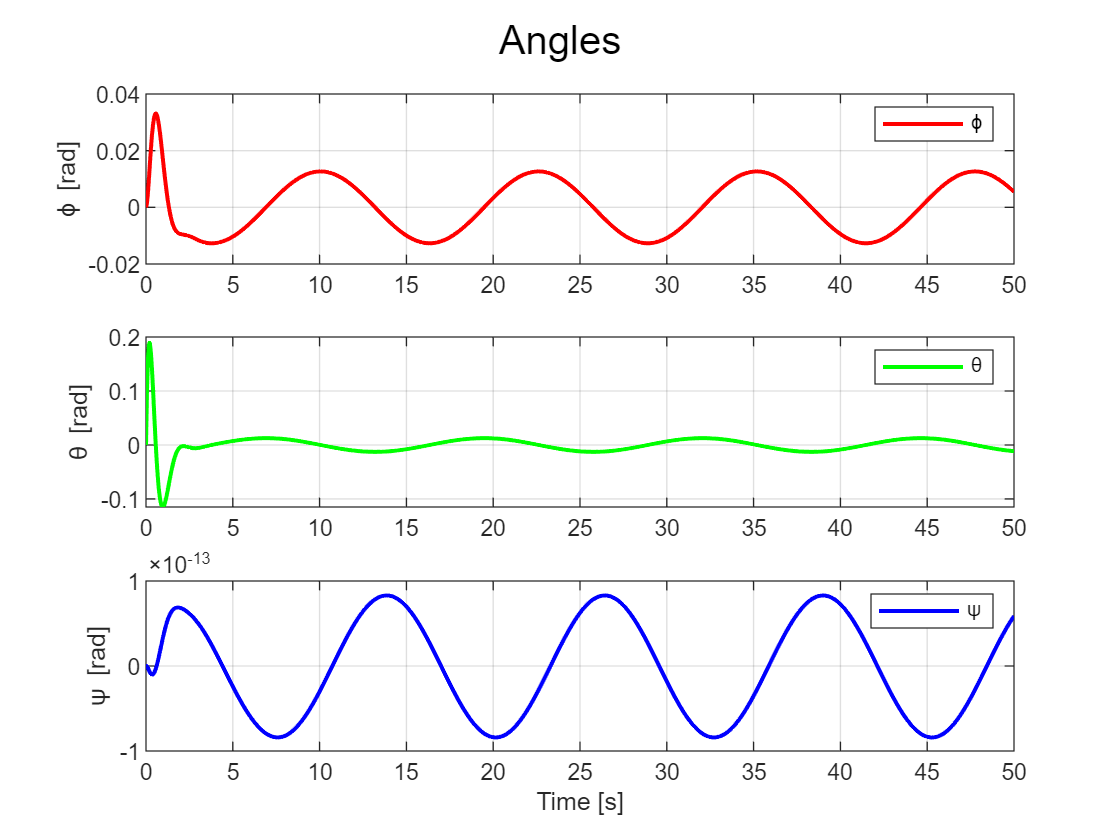

figure;
subplot(3,1,1);
plot(t, x(:,7), 'r', 'LineWidth', 1.5);
ylabel('\phi [rad]'); legend('\phi'); grid on;

subplot(3,1,2);
plot(t, x(:,9), 'g', 'LineWidth', 1.5);
ylabel('\theta [rad]'); legend('\theta'); grid on;

subplot(3,1,3);
plot(t, x(:,11), 'b', 'LineWidth', 1.5);
xlabel('Time [s]'); ylabel('\psi [rad]'); legend('\psi'); grid on;
sgtitle('Angles');

## Figure 4: Angular Rates φ', θ', ψ'

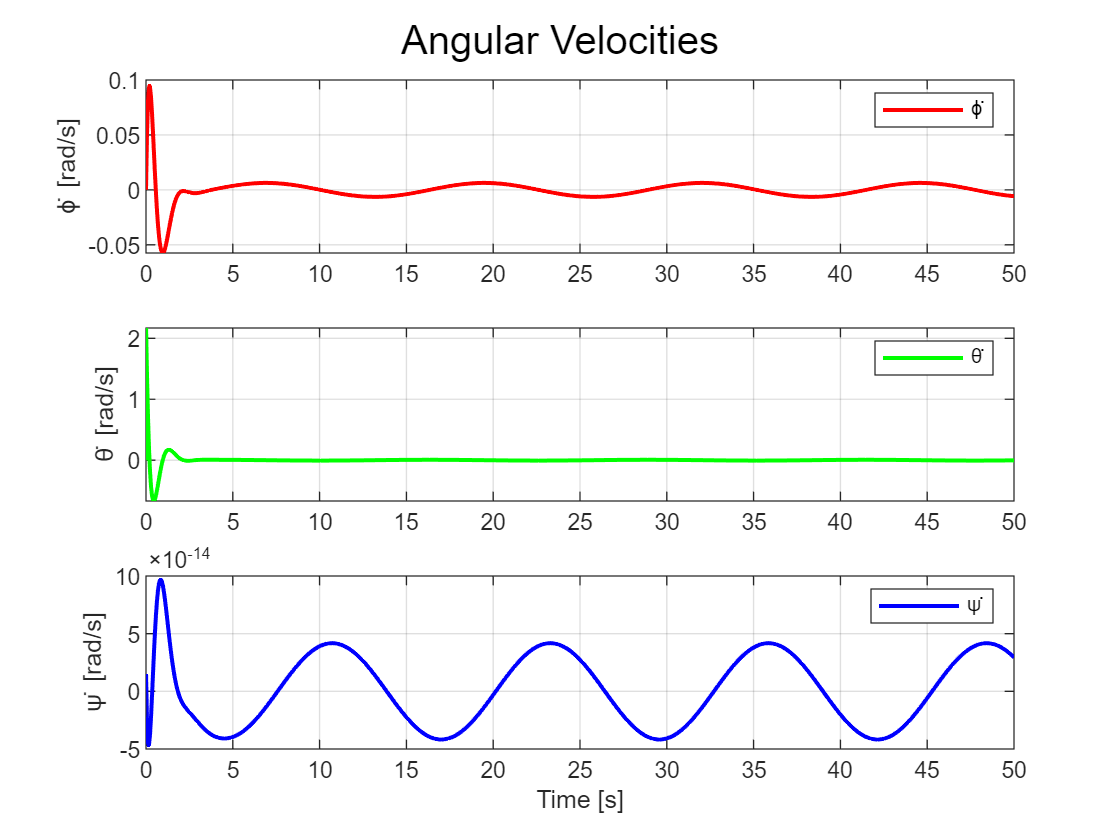

figure;
subplot(3,1,1);
plot(t, x(:,8), 'r', 'LineWidth', 1.5);
ylabel('\phi̇ [rad/s]'); legend('\phi̇'); grid on;

subplot(3,1,2);
plot(t, x(:,10), 'g', 'LineWidth', 1.5);
ylabel('\thetȧ [rad/s]'); legend('\thetȧ'); grid on;

subplot(3,1,3);
plot(t, x(:,12), 'b', 'LineWidth', 1.5);
xlabel('Time [s]'); ylabel('\psi̇ [rad/s]'); legend('\psi̇'); grid on;
sgtitle('Angular Velocities');

## 3D

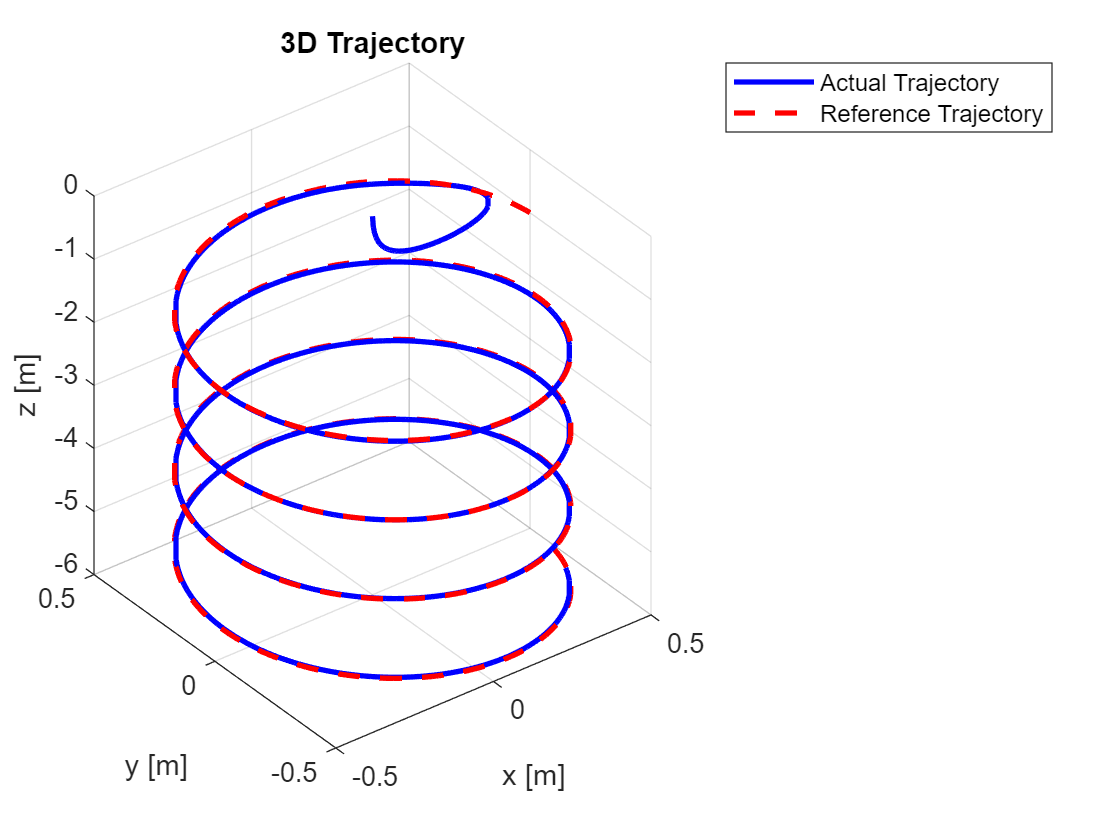

figure;
plot3(x(:,1), x(:,3), x(:,5), 'b', 'LineWidth', 2); hold on;
plot3(xod, yod, zod, 'r--', 'LineWidth', 2);
xlabel('x [m]');
ylabel('y [m]');
zlabel('z [m]');
legend('Actual Trajectory', 'Reference Trajectory');
grid on;
title('3D Trajectory');
view(3); 

## Figure 5: Tracking Error in x, y, z

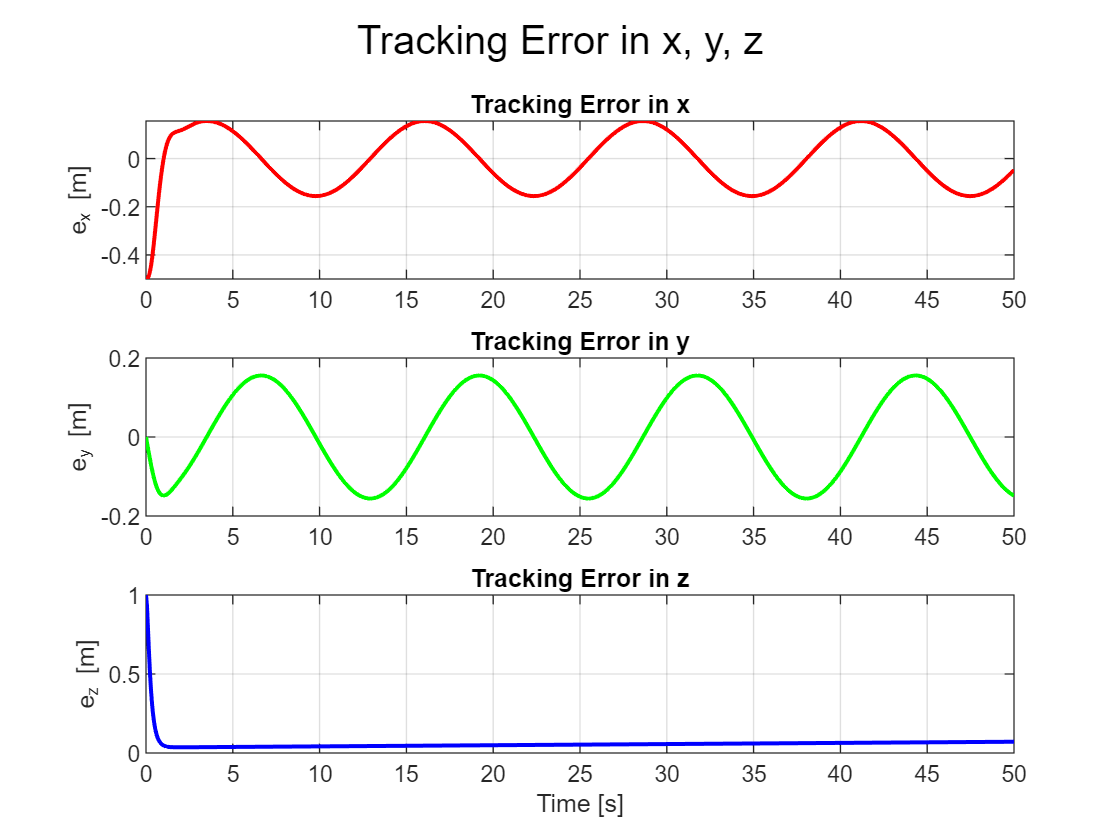

ex = x(:,1) - xod';
ey = x(:,3) - yod';
ez = x(:,5) - zod';

figure;
subplot(3,1,1);
plot(t, ex, 'r', 'LineWidth', 1.5);
ylabel('e_x [m]'); grid on; title('Tracking Error in x');

subplot(3,1,2);
plot(t, ey, 'g', 'LineWidth', 1.5);
ylabel('e_y [m]'); grid on; title('Tracking Error in y');

subplot(3,1,3);
plot(t, ez, 'b', 'LineWidth', 1.5);
xlabel('Time [s]'); ylabel('e_z [m]'); grid on; title('Tracking Error in z');

sgtitle('Tracking Error in x, y, z');

## Figure 6: Control Inputs u₁ to u₄

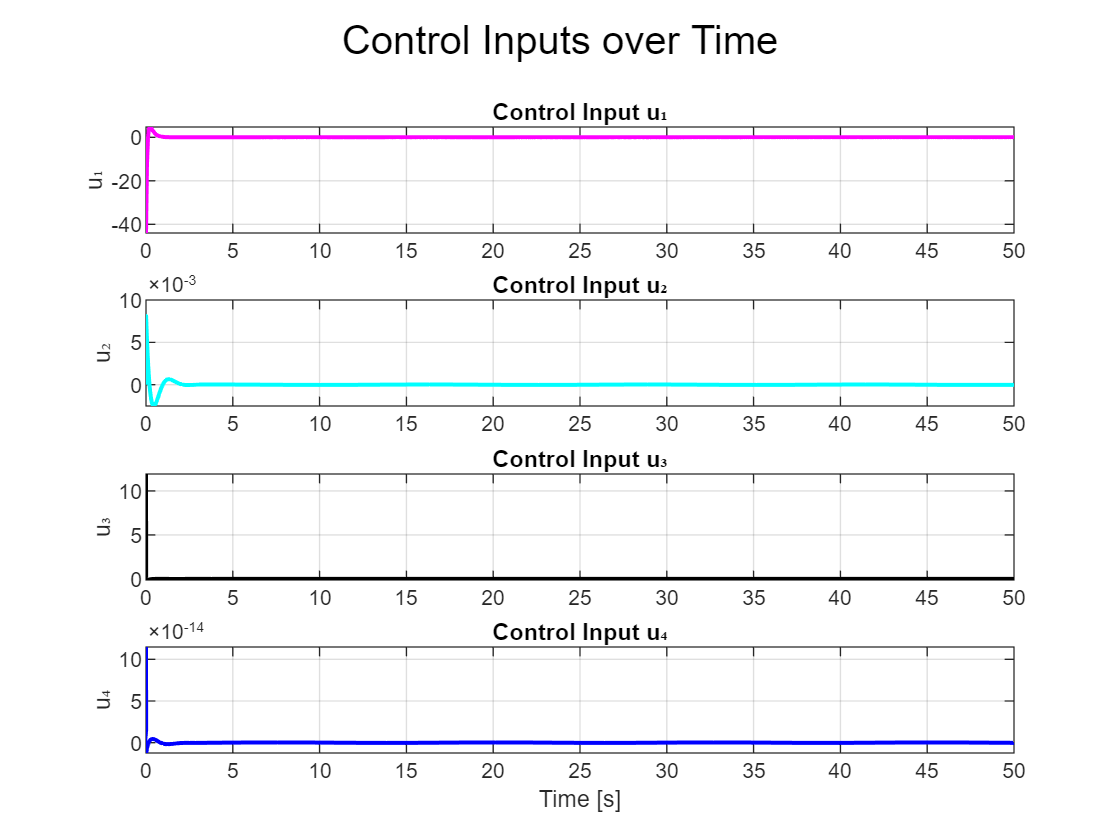

figure;
subplot(4,1,1);
plot(t, u(1,:), 'm', 'LineWidth', 1.5);
ylabel('u₁'); title('Control Input u₁'); grid on;

subplot(4,1,2);
plot(t, u(2,:), 'c', 'LineWidth', 1.5);
ylabel('u₂'); title('Control Input u₂'); grid on;

subplot(4,1,3);
plot(t, u(3,:), 'k', 'LineWidth', 1.5);
ylabel('u₃'); title('Control Input u₃'); grid on;

subplot(4,1,4);
plot(t, u(4,:), 'b', 'LineWidth', 1.5);
xlabel('Time [s]'); ylabel('u₄'); title('Control Input u₄'); grid on;

sgtitle('Control Inputs over Time');